## Problem 3

clear;
rng(0);

Simulate $N := 10^4$ independent random walkers (as discussed in class) along the real line, each walker starting at the origin, and each walker taking $10^3$ steps each of length $10^{-3}$ . 

N=10^4;  % number of walkers
nsteps=10^3;   % number of steps by each walker 
steplength=10^(-3);     % length of steps of each walker

steps=steplength*(randi([0,1],N,nsteps)*2 - 1); %  an array storing the steps of all the walkers
walkers=sum(steps,2);   % computing the final positions of walkers

- Plot a histogram of the final locations of all the random walkers. You may use the hist(.) function in Matlab. 

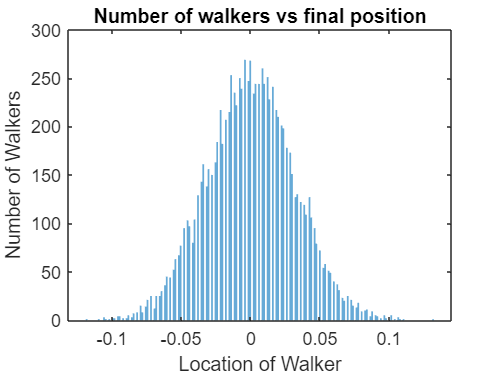

histogram(walkers, 200,'EdgeColor','none'), xlabel("Location of Walker"), ylabel("Number of Walkers"), title("Number of walkers vs final position");

- For the first $10^3$ walkers, plot space-time curves that show the path taken by each walker (as depicted in the class slides). On the graph, draw each path in a different randomly-chosen color for better clarity. 

firstw= steps(1:10^3,1:10^3);  % consider only the first 1000 walkers
positions= cumsum(firstw,2);    % calculate the final position of each walker

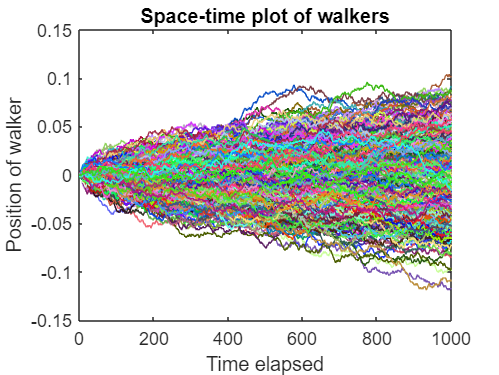


plot(positions(1,1:10^3), 'color', [rand(), rand(), rand()]), xlabel("Time elapsed"), ylabel("Position of walker"), title("Space-time plot of walkers");   % Space time plot
hold on;
for i=(2:10^3)
    plot(positions(i,1:10^3), 'color', [rand(), rand(), rand()]);
end

hold off;

- Consider a random variable $X$. Consider a dataset that comprises $N$ independent draws (e.g., modeled by $X_1, \cdots , X_N$ ) from the distribution of $X$. 

Use the law of large numbers to show that the random variable 


$$\hat{M} := \frac{\left(X_1 +\cdots+X_N \right)}{N}$$


converges to the true mean 


$$M := E[X]$$
 

as $N \rightarrow \infty$. 

Prove that the expected value of the random variable 


$$\hat{V} := \sum^N_{i=1} \frac{(X_i - \hat{M})^2}{N}$$


tends to the true variance 


$$V := Var(X)$$


as $N \rightarrow \infty$.

It can also be shown that the variance of the random variable $\hat{V}$ tends to zero as $N \rightarrow \infty$; the proof is a bit tedious though (see https://mathworld.wolfram. com/SampleVarianceDistribution.html). 

The result for $\hat{M}$follows directly from the law of large numbers. We proceed to show it for $\hat{V}$.


$$\hat{V} = \sum^N_{i=1} \frac{(X_i - \hat{M})^2}{N}$$



$$= \sum^N_{i=1} \frac{1}{N} \left( X_i^2 -2X_i\hat{M} + \hat{M}^2 \right)$$



$$= \sum^N_{i=1} \frac{X_i^2}{N}  - 2\hat{M}\sum^N_{i=1} \frac{X_i}{N} + \hat{M}^2$$



$$= \sum^N_{i=1} \frac{X_i^2}{N}  - \hat{M}^2$$


Using the weak law of large numbers on the first term , and the convergence of $\hat{M}$, as $N \rightarrow \infty$,


$$\longrightarrow E\left[X^2\right] - M^2$$



$$= Var(X)$$


- Report the empirically-computed mean $\hat{M}$ and the empirically-computed variance $\hat{V}$ of the final locations of the random walkers. 

mean_walkers=mean(walkers)    %empirical mean of positions

mean_walkers = 1.3860e-04

var_walkers=mean((walkers-mean_walkers).^2)    %empirical variance of positions

var_walkers = 0.0010

- What should the values of the true mean and the true variance be for the random variable that models the final location of the random walker, as function of the step length and the number of steps ? 

True mean = $0$

True variance = $npq$

mu_true=0;
var_true = 10^(-3); % npq

- Report the error between the empirically-computed mean and the true mean. Report the error between the empirically-computed variance and the true variance.

mu_err = abs(mean_walkers-mu_true)

mu_err = 1.3860e-04

var_err = abs(var_walkers-var_true)

var_err = 4.7684e-06

var_err_rel = var_err/var_true

var_err_rel = 0.0048